# *Assignment 4 -- Color and Multi-Scale Representations*

*Image and Video Processing*

## Ground Rules for the Assignment

- You can only use basic functions (matrix operations, input/output image functions, plotters). Anything else, you need to code from scratch (histogram functions, inverting gamma functions, color matting, histogram equalization).

- The code needs to be appropriately commented and should be reproducible; if we cannot re-generate your figures from your code, we will deduct points.

- The Live Script Report should be detailed and include partial and final soltuions for each exercise. We grade solely the `Report` part; code without report will not be graded, so we encourage that you invest some time on it.

- Interactive plots are welcome, but most important results should be static and generated beforehand.

- Remember to remove all plots and output from the `Task` sections. Only the `Report` should output plots and/or images.

## Submission Details

Simply submit this Live Script with the report inlined as described below. Name the file as `surname1_name1_surname2_name2_assignment1.mlx`

## 1 Color Palette Extraction from Images [8 Points]

Color palettes are a fundamental tool for both physical and digital artists. These sets of colors are a meaningful representation of all colors present in an image or piece of art, enabling the artist to tweak them for specific artistic effects. Purely decomposing an image into all of its colors can create "accurate" color palettes, but in natural images and paintings these would feature thousands of different colors and thus the palette becomes unmanageable. On the other extreme, a color palette solely composed of cyan, magenta and yellow (or red, green and blue in digital art) is a possible solution always, as these can create a wide range of visible colors, but they are not very helpful in describing the specific colors that best define a picture and thus using them to intuitively edit them or change their style is impossible. Best color palettes for digital image editing not only describe the colors that best define the style of a picture, but rather do so in a localized or semantic way. For example, the color of human skin and of a building painted pink could be rendered with similar colors, but editing them together to change the style of our picture would probably be undesired.

### 1.1 Linear RGB and sRGB Color Palettes

In this exercise, we ask you to implement a simple way of extracting a meaningful and interesting color palette from a single image. The end result will be the decomposition of the original image into a set of color layers that together add up to the initial image. We will first ask you to compute two different palettes, one starting from the image `queen.jpg` in linear RGB space, and the other in sRGB space. The process can be broadly described in 3 steps:

- Loading Image in RGB space: Load the image and implement your own function to transform it to linear RGB (invert sRGB transform, see Lecture #8).

- Color Clustering: We will now cluster those colors according to color similarity in RGB and sRGB spaces (this means that similar values will be clustered together, and its average will be a distinct palette color). To do this, you will use K-means clustering, so that they are divided in 7 clusters, selecting the centroid of each as representing color. You can use MATLAB’s function kmeans, but to do so you will first need to install MATLAB’s Statistics and Machine Learning Toolbox.

- Image Decomposition into Base Color Layers: Now that you have your color palette, we will create 7 layers where we select only the pixels of the image whose colors we included in each individual cluster (see Figure 1). All other pixels will be set to black. The resulting layers will together add up to the initial image. Finally, translate each layer into HSL color space. This will enable intuitive editing of similar colors together, and applying changes to the image will limit to a simple addition of all layers. Additionally, draw a color strip with the centroids (average colors) of each filter/layer, which will be the representing colors of your palette (Figure 1).

Include a figure in your report with your resulting color layers from this step. Compare both linear and standard RGB palettes, arguing about quality.

% Add your code here. 
% You can include comments in your code
% explaining the steps of your algorithm.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*

### 1.2 CIELab Color Palette

You may have noticed that some clusters in your color palette are featuring colors that are quite different from each other, making editing a bit difficult. This is due sRGB not being a perceptually-uniform color space, which makes perceived and numerical differences between colors differ greatly. Perceptually uniform color spaces, such as CIELab, exploit computational models of human perception to create color spaces where geometric distances roughly correspond to similar distances in the perceptual space. This should ensure better color separation in your palette (Figure 1).

Edit your palette generation algorithm to use CIELab color space. You may use existing MATLAB/Python functions to translate your image from sRGB to CIELab. Compare both methods.

You can now edit the artistic look of your image intuitively by changing the individual color layers! Play around with them and generate some results of your own. You can try shifting the hue of specific layers, or plainly increasing lightness or saturation for specific effects. You should try it in at least 1 image of your own choice. Include the produced palette and filtered layers of the provided `queen.jpg` image as well.

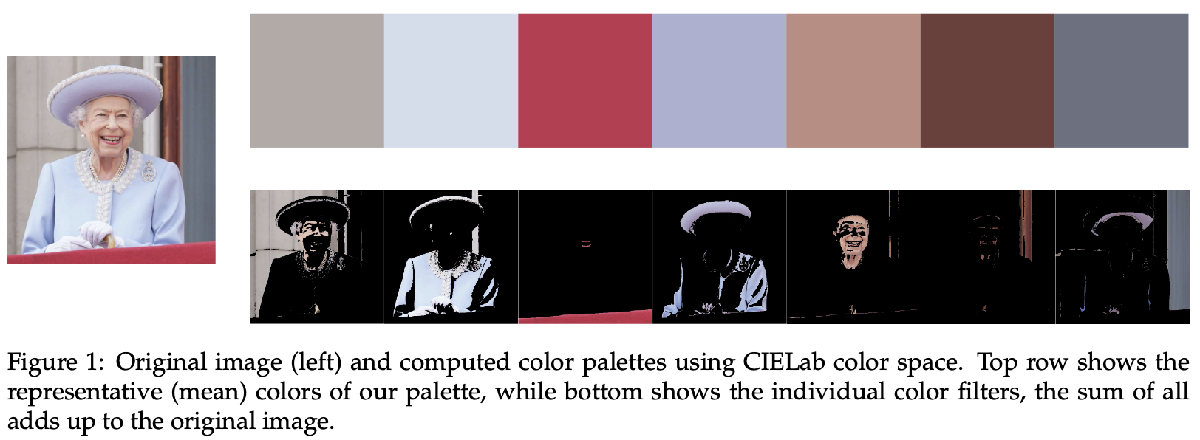

**Bonus [1.5 Points]:** An important tool when editing the colors and overall feel of an image is white balance. As we saw in Assignment #1, obtaining a neutral, calibrated white balance is important for accurate photographic reproduction, but we can also alter it for artistic purposes. Recover your white balance code from Assignment #1 and try increasing or decreasing the temperature of your image after computing your color palette. Try then combining it with your palette-based color editing and other simple point operations we saw in Assignment #1 (contrast, brightness) to create your own tiny Lightroom! Showcase it with a picture of your choice.

% Add your code here.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*

## 2 Color Quantization and Lookup Tables (LUTs) [4 Points]

Quantization and color mapping through LUTs are techniques used in image processing to transform the color space of an image, either to reduce the amount of data required to represent the image, or to map colors from one space to another.

Quantization involves reducing the number of colors in an image by mapping similar colors to a smaller set of discrete values. This can be done by dividing the color space into a regular grid, and assigning each pixel to the closest grid point. This process is commonly used in image compression, as it reduces the amount of data required to represent the image, by storing per-pixel color IDs instead of exact colors. However, it can also cause loss of detail and introduce visual artifacts.

LUTs are used to map one set of values to another set of values. In image processing, LUTs are commonly used to map colors from one color space to another. For example, they can be used to convert an RGB image to a grayscale image, by mapping each pixel’s RGB values to a specific grayscale value. LUTs are also widely used in cinema production to apply color grading effects to an image or video, by mapping the original colors to new, adjusted colors, to achieve specific artistic effects.

**Task.** Implement a basic quantization method to reduce the size of the provided image by mapping its pixel values to a set of 32 colors. You may use any method to constrain this color space, except pre-defined MATLAB/Python solutions, of course. A few suggestions are, but not limited to: color clipping, thresholding, clustering, palette-based or euclidean distance-based nearest neighbors. Then, implement a look-up table that transforms your compressed RGB image into a grayscale image. You are also free to choose any method to map your 32 quantized colors to grey values, taking luminance, color difference or hue into account, for example. Try to maximize perceived quality, and make sure to explain in detail your approach for both quantization and LUT color mapping in you report. Show both your quantized color image and your resulting grayscale image after applying your LUT in the provided `queen.jpg` image.

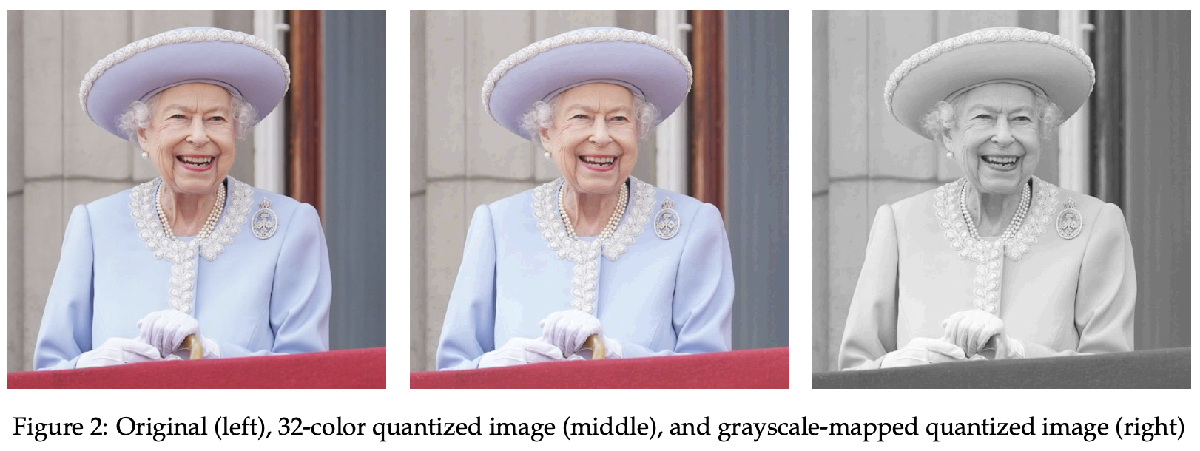

**Bonus [1.5 Points]: **Make your color quantization pipeline perceptually-aware, by exploiting human color and luminance perception to quantize colors more aggressively or making quantization less obvious. Use the Weber-Fechner Law and perceptual color models like CAM or CIELab to improve quantization. Show this improvement comparatively.

% Add your code here.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*

## 3 Gaussian and Laplacian Pyramids [5 Points]

Multi-scale image representations (also called pyramids) transform an image into a set of images representing different frequency bands in the original image. While a Gaussian pyramid stores different low-pass versions of the original image, every level of Laplacian pyramid stores a specific range of spatial frequencies which correspond to band-passed versions of the original images. When all levels of Laplacian pyramid are added the result is the original image. This is not true for Gaussian pyramids.

**Task.** Implement a function to compute a Laplacian pyramid of an input image. The code should decompose the image into 4 levels. You are allowed to use MATLAB/Python functions for spatial filtering and resizing images. The most straightforward way to realize this task is to first build the Gaussian pyramid, and then subtract the consecutive levels to obtain the individual levels of the Laplacian pyramid (the procedure we described during the lecture). Compute the Laplacian pyramid of the two provided images (`sad.jpg` and `happy.jpg`) and show the different levels of your pyramid in your report.

% Add your code here.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*

## **4 Hybrid Images [3 Points]**

A fun application of Gaussian and Laplacian pyramids is the creation of hybrid images. In essence, the human visual system is sensitive to high-frequency content of the image at close distances, but the further we move from the image our sensitivity and ability to resolve high-frequency content diminishes, and we better perceive low-spatial frequencies of the image. This can be exploited to create images which combine the high frequency component of one image with the low frequency component of another, resulting in an image that changes its appearance depending on the distance from which it is observed. A simple way of creating a hybrid image is to combine two different levels of Laplacian pyramids constructed for the input images. Another simple way is to filter one image with a low-pass filter and the other with complementary high-pass filter, and add the images together.

**Task.** Use one of the methods to compute hybrid images out of the two images `sad.jpg` and `happy.jpg` provided with the assignment. You should be able to get a similar effect to what you can see in Figure 3. If you use the first approach to computing hybrid images, play around with which levels to combine. When you use the second method, experiment with different cut-off frequencies for both filters. In both cases, see how the choices influence the quality of the results and the distances from which the images should be observed.

In the report provide the final image with information about the ideal viewing conditions:

- the size of the image on the screen

- the distance to see sad face

- the viewing distance to see happy face

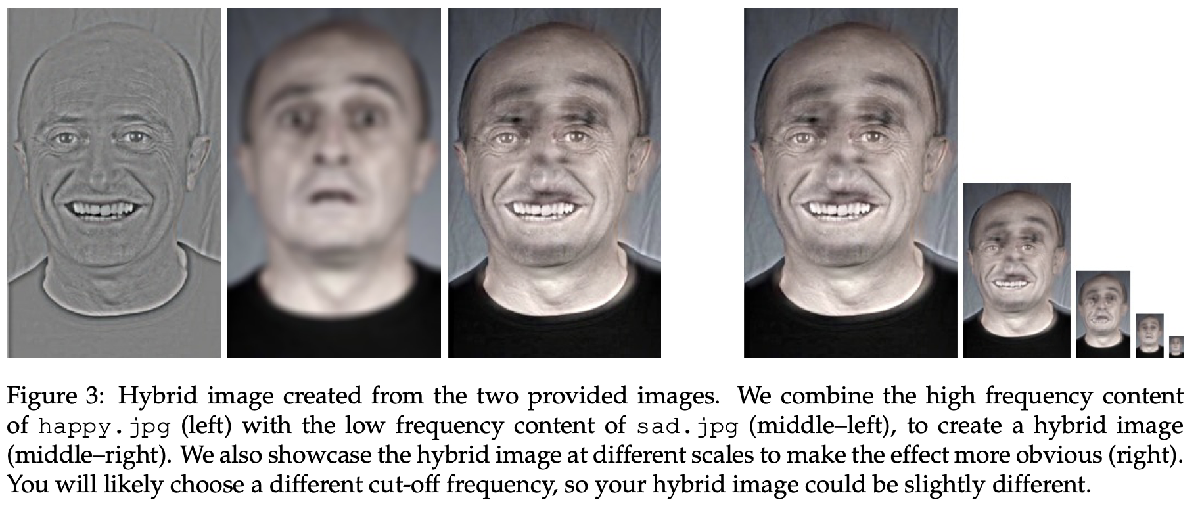

% Add your code here.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*

## 5 Bonus: Create your own Instagram Filter! [2 Points]

You may use now your newly acquired tools in image filtering and color manipulation to create your own Instagram filter! A possible approach can be to select a specific artist or photographer you like to emulate their style, or pick a known filter you want to reproduce. You can then employ specific color mappings or filtering methods from this and previous assignments to develop your own artistic rendition. You may also try your hand at color harmonization, as seen in Lecture #8. We only impose two rules:

- Your filter should be plug-and-play, that is, we have to be able to use it on any image, regardless of colors, image size, etc.

- It should be implemented as a single compact MATLAB/Python function so that we can test it out ourselves.

Otherwise, we give you full freedom to use any tool you want! Apply it to several of your own images, and showcase your solution with step-by-step partial result images illustrating the process from base image to your final result. Remember to include your source of inspiration as well in the report. Note: Copy pasting the grayscale effect developed in Exercise 2 will not render extra points. You can see an example filter developed by us in Figure 4.

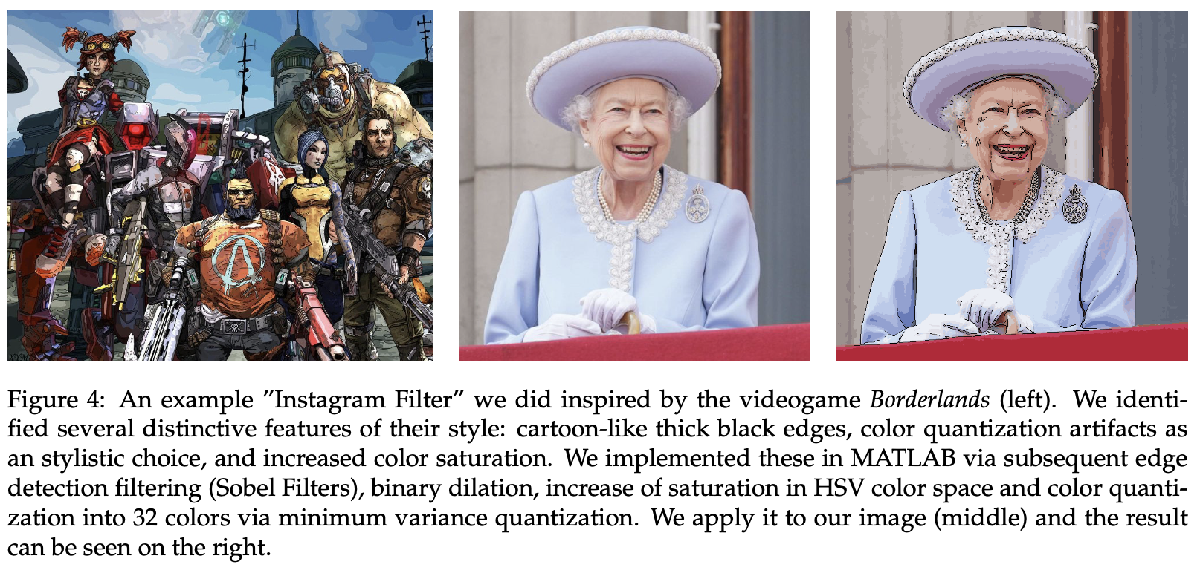

% Add your code here.

**Report. *** Add your report here.*

% Inline your images here.

*... Add your report here.*